# Paper2 Fig5: Activity maps

## Setting up WS

CurrentFolder = pwd
addpath(CurrentFolder)
addpath([CurrentFolder '/Utils'])
addpath([CurrentFolder '/Data'])
DataFolder = [CurrentFolder '/Data/Paper2_NetworkTuning/Fig1V4/Paper2PlotingData/']; % V1D2
DataFolder2 = [CurrentFolder '/Data/Paper2_NetworkTuning/Fig1V4/Paper2PlotingData/Typical_trajs/']; % V1D2
%DataFolder1 = [CurrentFolder '/Data/Paper2_NetworkTuning/Fig1V4/GlobConv/']; % V1D2

addpath(DataFolder2)
addpath(DataFolder)
addpath([CurrentFolder '/Data/Paper2_NetworkTuning/Fig1V4/'])

FigurePaperPath = [CurrentFolder '/Paper2Figs/']; % V1D2

### B1. Load LDE computations and do Fr distributions

Should rerun Sect 1 after in case loaded file contain any paths.

DataPoint = 'V4D2'; %'V4D1'; 'V5D1'
load(sprintf("AllMFPixPara_Paper2TuneFig1%s.mat",DataPoint))

close all

## 2. Load Data sets

first get basic function information

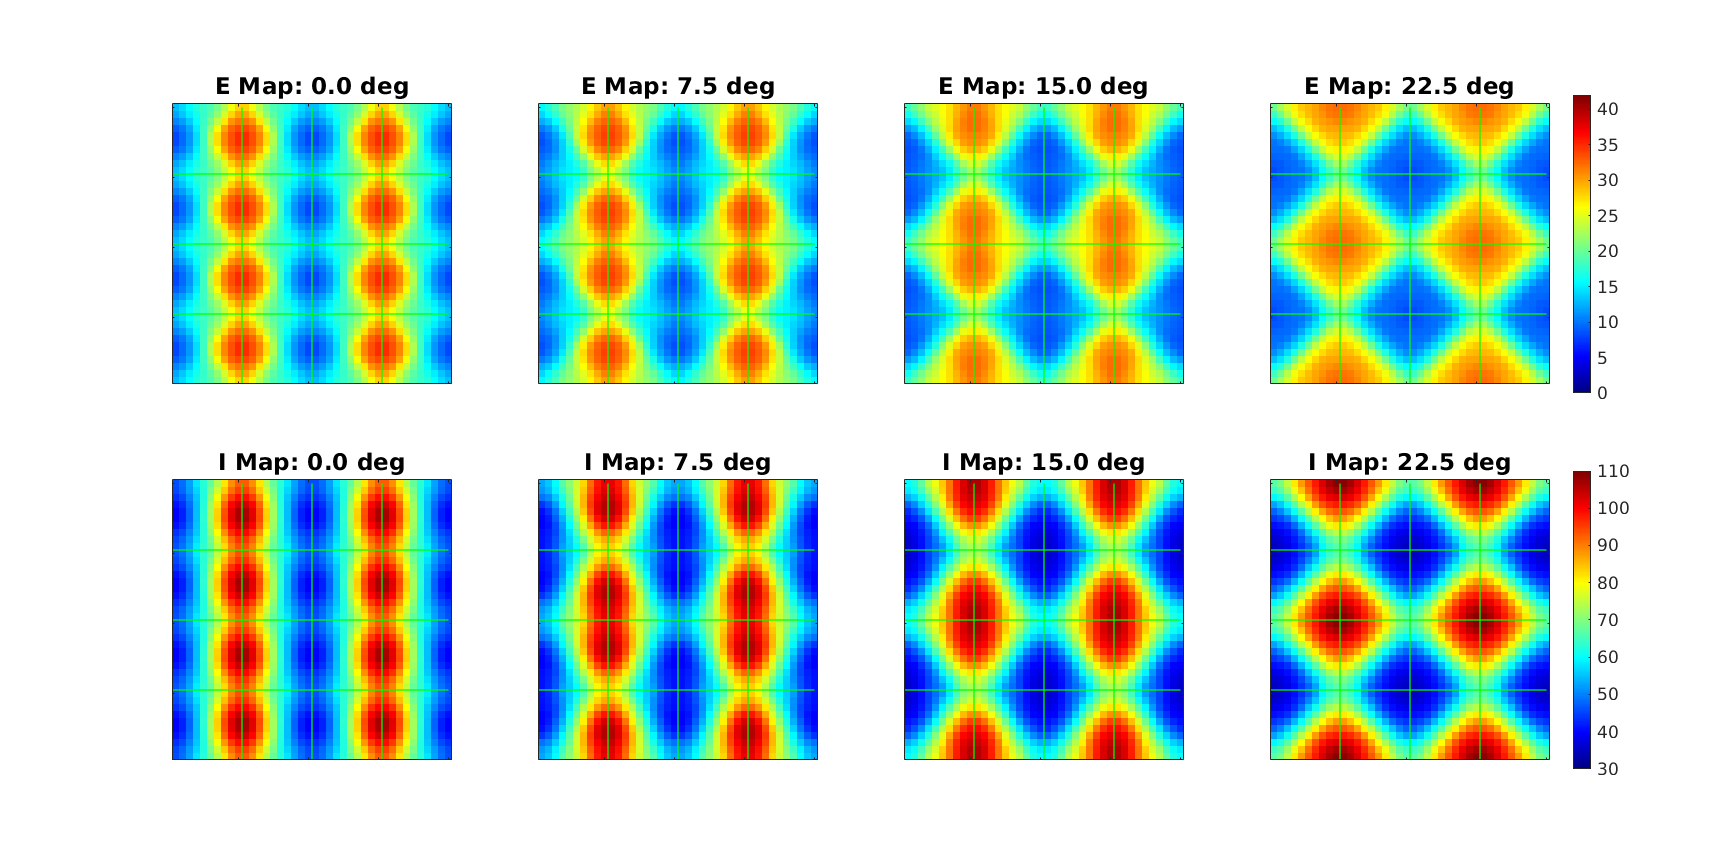

AngleList = {'0.0','7.5','15.0','22.5'};

Fig5 = figure("Name",'NESSs','units','normalized','outerposition',[0,0,0.35,0.45]);
Panel1 = 2; Panel2 = 4;%length(EpocList);
ha = tight_subplot(Panel1,Panel2,[.03 .05],[.08 .08],[.10 .10]);
Caxe = [0 42; 30 110];

N_HCOut = 4;
PixNumOut = N_HCOut*NPixX*N_HCOut*NPixY;

for AngInd = 1:length(AngleList)
    AngPrint = AngleList{AngInd};
    PlotUse = load([DataFolder2 sprintf('LDETraces_bg-ang%s.mat',AngPrint)],'LDEEquv');
    Patt = PlotUse.LDEEquv;
    
    axes(ha(AngInd)); % E panel
    ShowField(...
        Patt.S*(1-CplxR)+Patt.C*CplxR,...
        1:PixNumOut,N_HCOut*NPixX,N_HCOut*NPixY,...
        sprintf('E Map: %s deg',AngPrint), Caxe(1,:)) % last input may catgorized cbar: ,, [5 60]
    set(gca,'fontsize',16)
    set(gca,'YTickLabel',[]);
    set(gca,'XTickLabel',[]);
    colorbar off
    ax1 = gca;
    
    axes(ha(AngInd+Panel2)); % E panel
    ShowField(...
        Patt.I,...
        1:PixNumOut,N_HCOut*NPixX,N_HCOut*NPixY,...
        sprintf('I Map: %s deg',AngPrint), Caxe(2,:)) % last input may catgorized cbar: ,, [5 60]
    set(gca,'fontsize',16)
    set(gca,'YTickLabel',[]);
    set(gca,'XTickLabel',[]);
    colorbar off
    ax2 = gca;
    
    if AngInd == Panel2
            Pos1 = get(ax1,'Position');
            Pos2 = get(ax2,'Position');
    end
    
end

cbr1 = colorbar(ax1, 'Position', [Pos1(1)+Pos1(3)+0.05  Pos1(2)+0.03  0.01  Pos1(4)-0.06]);
caxis(Caxe(1,:))
set(cbr1,'YTick',0:5:40,'FontSize',13)

cbr2 = colorbar(ax2, 'Position', [Pos2(1)+Pos2(3)+0.05  Pos2(2)+0.03  0.01  Pos2(4)-0.06]);
caxis(Caxe(2,:))
set(cbr2,'YTick',0:10:110,'FontSize',13)

Save figures

FigName1 = sprintf('Figure5Draft');
savefig(Fig5,[FigurePaperPath FigName1 '.fig']);


Print Figs

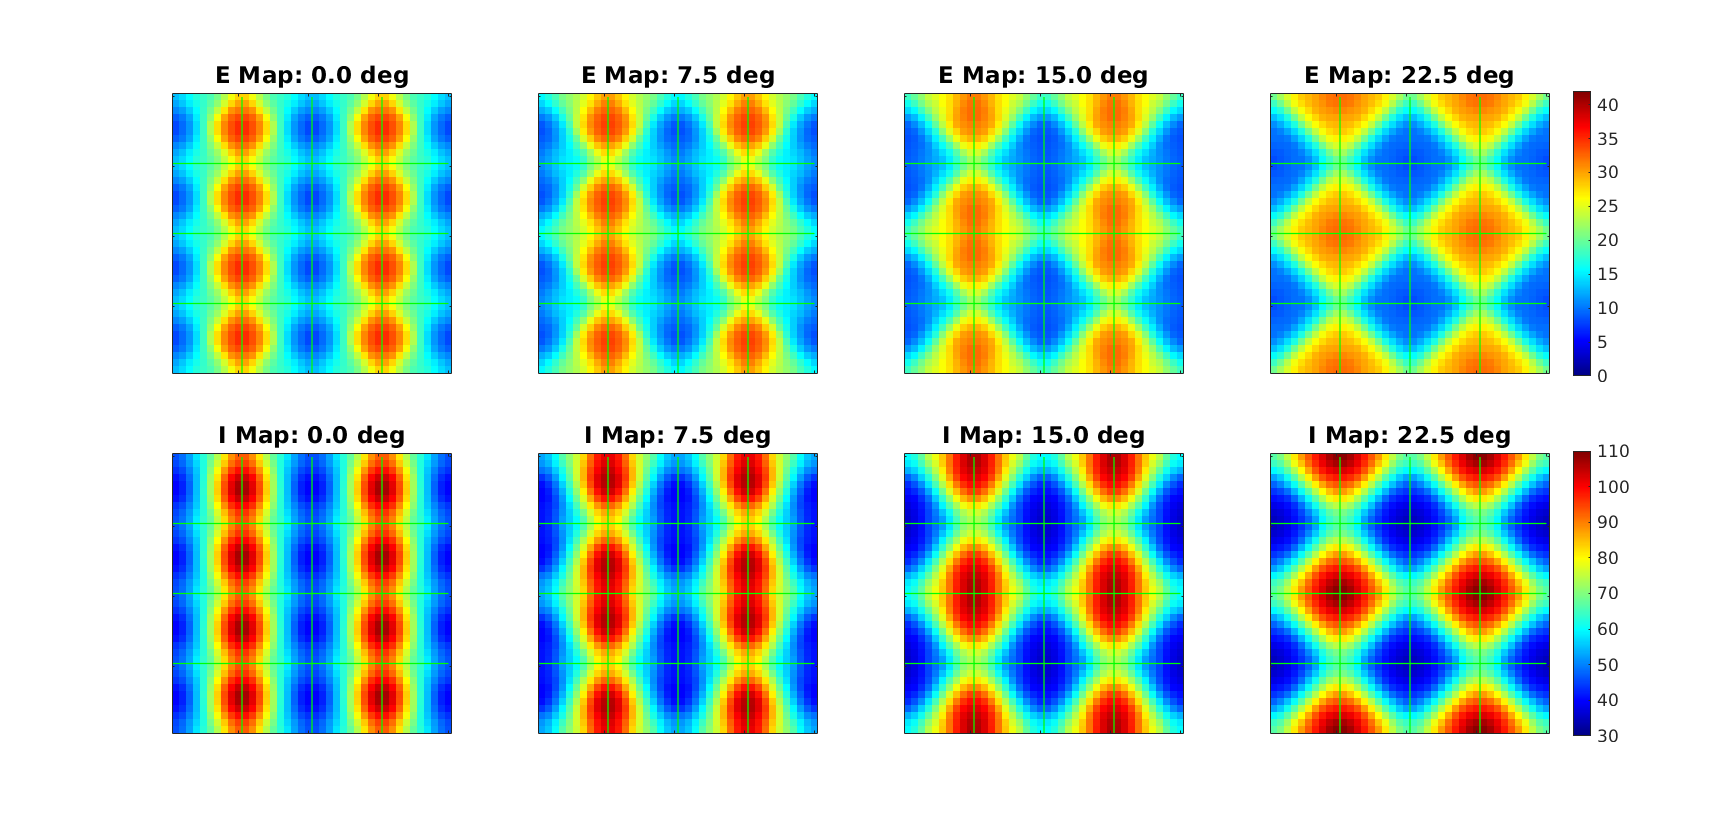

Fig5.PaperUnits = 'centimeters';
Fig5.PaperSize = [36,24];
Fig5.PaperOrientation = "landscape";
exportgraphics(Fig5,[FigurePaperPath FigName1 '.pdf'],'Resolution',300)